% cross section at spar location
h = 0.2 % m

h = 0.2000

b = 0.2 % m

b = 0.2000


t_skin = 0.5e-3

t_skin = 5.0000e-04

t_boom = 1e-3

t_boom = 1.0000e-03

V_y = -40

V_y = -40

total_lift = 6.8*9.8

total_lift = 66.6400


% We wiil assume distributed lift at the top
lift_distrib = (total_lift/2)/(b/2)

lift_distrib = 333.2000


Area_boom = 20e-3*t_boom

Area_boom = 2.0000e-05


I_skin = (1/12)*( b*h^3 - (b-2*t_skin)*(h-2*t_skin)^3)

I_skin = 2.6467e-06

I_boom = 4*Area_boom*(h/2)^2

I_boom = 8.0000e-07


I_total = I_skin + I_boom

I_total = 3.4467e-06


% C_section bulkhead

length_middle = 15e-3

length_middle = 0.0150

length_flange = 25e-3

length_flange = 0.0250

As = (2*length_flange + length_middle)*t_boom

As = 6.5000e-05


E = 70e9;       % Young's modulus [Pa]
G = 26e9;       % Shear modulus [Pa]



syms s n m f 

% n - Axial unknown
% f - Shear unknown
% m - moment unknown


% From 0 to 1
L1 = b/2

L1 = 0.1000


Axial_1 = n + (V_y*t_skin*h/(2*I_total))*(s^2/2) % Integral of Shear flow

$$Axial\_1 = n-\frac{5104017273287963\,s^{2}}{17592186044416}$$

Shear_1 = f 

$$Shear\_1 = f$$

Moment_1 = m - f*s

$$Moment\_1 = m-f\,s$$


% loads at junction 1 

m_1 = m - f*b/2

$$m\_1 = m-\frac{f}{10}$$

n_1 = n + (V_y*t_skin*h/(2*I_total))*b^2/8

$$n\_1 = n-\frac{3266571054904297}{1125899906842624}$$

f_1 = f

$$f\_1 = f$$


% From 1 to 2

L2 = h

L2 = 0.2000


Axial_2 = f_1 + (V_y/I_total)*( (b*t_skin*h/4 + Area_boom*h/2)*s + h*t_skin*s^2/2 - t_skin*s^3/3 )

$$Axial\_2 = \frac{1246097967111319\,s^{3}}{644245094400}-\frac{1246097967111319\,s^{2}}{2147483648000}-\frac{6436206081220228868065281662325\,s}{79228162514264337593543950336}+f$$

Shear_2 = -n_1

$$Shear\_2 = \frac{3266571054904297}{1125899906842624}-n$$

Moment_2 = m_1 + n_1*s

$$Moment\_2 = m-\frac{f}{10}+s\,\left(n-\frac{3266571054904297}{1125899906842624}\right)$$


% loads at junction 2

L3 = b/2

L3 = 0.1000


m_2 = subs(Moment_2,s,h)

$$m\_2 = m-\frac{f}{10}+\frac{n}{5}-\frac{3266571054904297}{5629499534213120}$$

n_2 = subs(Axial_2,s,h)

$$n\_2 = f-\frac{17814498974805990007802512678944751}{742764023571228164939474534400000}$$

f_2 = subs(Shear_2,s,h)

$$f\_2 = \frac{3266571054904297}{1125899906842624}-n$$


% From 2 to 3

Axial_3 = f_2 + V_y*t_skin*h/(4*I_total)*(b*s - s^2)

$$Axial\_3 = \frac{5104017273287963\,s^{2}}{17592186044416}-\frac{5104017273287963\,s}{87960930222080}-n+\frac{3266571054904297}{1125899906842624}$$

Shear_3 = lift_distrib*s - n_2

$$Shear\_3 = \frac{1666\,s}{5}-f+\frac{17814498974805990007802512678944751}{742764023571228164939474534400000}$$

Moment_3 = lift_distrib*s^2/2 - m_2 - n_2*s

$$Moment\_3 = \frac{833\,s^{2}}{5}+\left(\frac{17814498974805990007802512678944751}{742764023571228164939474534400000}-f\right)\,s+\frac{f}{10}-m-\frac{n}{5}+\frac{3266571054904297}{5629499534213120}$$

U1_bending = int( Moment_1^2/(2*E*I_total), s,0,L1)

$$U1\_bending = \frac{2147483648\,f^{2}}{3108757383225023625}-\frac{4294967296\,f\,m}{207250492215001575}+\frac{8589934592\,m^{2}}{41450098443000315}$$


U1_axial = int( Axial_1^2/(2*E*As), s,0,L1)

$$U1\_axial = \frac{268435456\,n^{2}}{24427626496000005}-\frac{5104017273287963\,n}{240133339506278449152000}+\frac{26050992326021892781052720689369}{1408156794687120350928129956511744000000}$$


U1_Shear = int( Shear_1^2/(2*G*As), s,0,L1)

$$U1\_Shear = \frac{1073741824\,f^{2}}{36292473651200005}$$


U1 = U1_bending + U1_axial + U1_Shear

$$U1 = \frac{683188063349785347173122048\,f^{2}}{22564899083733529266919385145023625}-\frac{4294967296\,f\,m}{207250492215001575}+\frac{8589934592\,m^{2}}{41450098443000315}+\frac{268435456\,n^{2}}{24427626496000005}-\frac{5104017273287963\,n}{240133339506278449152000}+\frac{26050992326021892781052720689369}{1408156794687120350928129956511744000000}$$

U2_bending = int( Moment_2^2/(2*E*I_total), s,0,L2)

$$U2\_bending = \frac{17179869184\,{\left(n-\frac{3266571054904297}{1125899906842624}\right)}^{2}}{3108757383225023625}+\frac{17179869184\,{\left(\frac{f}{10}-m\right)}^{2}}{41450098443000315}-\frac{17179869184\,\left(n-\frac{3266571054904297}{1125899906842624}\right)\,\left(\frac{f}{10}-m\right)}{207250492215001575}$$


U2_axial = int( Axial_2^2/(2*E*As), s,0,L2)

$$U2\_axial = \frac{536870912\,f^{2}}{24427626496000005}-\frac{17814498974805990007802512678944751\,f}{33795763072490888422275118956281856000000}+\frac{546775735313480736559082052344696042600887622230477297306973052098359}{125511384796916323190007090230888181187522184197749473103839232000000000000}$$


U2_Shear = int( Shear_2^2/(2*G*As), s,0,L2)

$$U2\_Shear = \frac{2147483648\,{\left(n-\frac{3266571054904297}{1125899906842624}\right)}^{2}}{36292473651200005}$$


U2 = U2_bending + U2_axial + U2_Shear

$$U2 = \frac{1459901119153278133924265984\,{\left(n-\frac{3266571054904297}{1125899906842624}\right)}^{2}}{22564899083733529266919385145023625}-\frac{17814498974805990007802512678944751\,f}{33795763072490888422275118956281856000000}+\frac{17179869184\,{\left(\frac{f}{10}-m\right)}^{2}}{41450098443000315}+\frac{536870912\,f^{2}}{24427626496000005}-\frac{17179869184\,\left(n-\frac{3266571054904297}{1125899906842624}\right)\,\left(\frac{f}{10}-m\right)}{207250492215001575}+\frac{546775735313480736559082052344696042600887622230477297306973052098359}{125511384796916323190007090230888181187522184197749473103839232000000000000}$$

U3_bending = int( Moment_3^2/(2*E*I_total), s,0,L3)

$$U3\_bending = \frac{447213469696\,f}{77718934580625590625}-\frac{3577707757568\,m}{15543786916125118125}-\frac{3577707757568\,n}{77718934580625590625}-\frac{4294967296\,\left(f-\frac{17814498974805990007802512678944751}{742764023571228164939474534400000}\right)\,\left(\frac{f}{10}-m-\frac{n}{5}+\frac{3266571054904297}{5629499534213120}\right)}{207250492215001575}+\frac{2147483648\,{\left(f-\frac{17814498974805990007802512678944751}{742764023571228164939474534400000}\right)}^{2}}{3108757383225023625}+\frac{8589934592\,{\left(\frac{f}{10}-m-\frac{n}{5}+\frac{3266571054904297}{5629499534213120}\right)}^{2}}{41450098443000315}+\frac{23749572203335463259955665010644830383}{35841532397254386252983107143598080000000000}$$


U3_axial = int( Axial_3^2/(2*E*As), s,0,L3)

$$U3\_axial = \frac{268435456\,n^{2}}{24427626496000005}-\frac{81664276372607459\,n}{3842133432100455186432000}+\frac{20007162106384827538775472832699087}{1081464418319708429512803806601019392000000}$$


U3_Shear = int( Shear_3^2/(2*G*As), s,0,L3)

$$U3\_Shear = \frac{1073741824\,{\left(f-\frac{17814498974805990007802512678944751}{742764023571228164939474534400000}\right)}^{2}}{36292473651200005}-\frac{894426939392\,f}{907311841280000125}+\frac{21711421453370935545055320330898065583}{627635599917687885842968827081523200000000}$$


U3 = U3_bending + U3_axial + U3_Shear

$$U3 = \frac{268435456\,n^{2}}{24427626496000005}-\frac{3577707757568\,m}{15543786916125118125}-\frac{17860347678767973625687867157398087\,n}{265428014986177556691245715947932876800000}-\frac{4294967296\,\left(f-\frac{17814498974805990007802512678944751}{742764023571228164939474534400000}\right)\,\left(\frac{f}{10}-m-\frac{n}{5}+\frac{3266571054904297}{5629499534213120}\right)}{207250492215001575}-\frac{552865173704967382285108117504\,f}{564122477093338231672984628625590625}+\frac{683188063349785347173122048\,{\left(f-\frac{17814498974805990007802512678944751}{742764023571228164939474534400000}\right)}^{2}}{22564899083733529266919385145023625}+\frac{8589934592\,{\left(\frac{f}{10}-m-\frac{n}{5}+\frac{3266571054904297}{5629499534213120}\right)}^{2}}{41450098443000315}+\frac{478213695584630450451966207805693805617799625408512141743301810791176427}{13557297478907112746616828750577526070540124313445109129329267179520000000000}$$

U = simplify(U1 + U2 + U3)

$$U = \frac{3185090480669377436768075580519244500041728\,f^{2}}{36747128449158359663245789835483615946192915007875}-\frac{8589934592\,f\,m}{69083497405000525}-\frac{4294967296\,f\,n}{345417487025002625}-\frac{146098480154104729306941197110261789708581452697219544656309461398457\,f}{50839865545901672799813107814665722764525466175419159234984751923200000000}+\frac{34359738368\,m^{2}}{41450098443000315}+\frac{34359738368\,m\,n}{207250492215001575}-\frac{43303969114157951659091653173280751\,m}{35841532397254386252983107143598080000000}+\frac{697940591699219070609438284080220695691264\,n^{2}}{7349425689831671932649157967096723189238583001575}-\frac{1295286692329286903476687976824731955360910442066857569622122506917\,n}{2118327731079236366658879492277738448521894423975798301457697996800000000}+\frac{2188964465015900120494879408708904067942143388945420016704463557509399422589786281104776018622346516903}{37762023090694180752773886899214407642672733902117726185125708114451866789811765008947824558080000000000000}$$

% dU/dn = 0
% dU/df = 0
% dU/dm = 0

eq1 = diff(U,n) == 0

$$eq1 = \frac{34359738368\,m}{207250492215001575}-\frac{4294967296\,f}{345417487025002625}+\frac{1395881183398438141218876568160441391382528\,n}{7349425689831671932649157967096723189238583001575}-\frac{1295286692329286903476687976824731955360910442066857569622122506917}{2118327731079236366658879492277738448521894423975798301457697996800000000}=0$$

eq2 = diff(U,f) == 0

$$eq2 = \frac{6370180961338754873536151161038489000083456\,f}{36747128449158359663245789835483615946192915007875}-\frac{8589934592\,m}{69083497405000525}-\frac{4294967296\,n}{345417487025002625}-\frac{146098480154104729306941197110261789708581452697219544656309461398457}{50839865545901672799813107814665722764525466175419159234984751923200000000}=0$$

eq3 = diff(U,m) == 0

$$eq3 = \frac{68719476736\,m}{41450098443000315}-\frac{8589934592\,f}{69083497405000525}+\frac{34359738368\,n}{207250492215001575}-\frac{43303969114157951659091653173280751}{35841532397254386252983107143598080000000}=0$$


sol = solve([eq1,eq2,eq3],[n,f,m])

sol = struct with fields:
    n: 2078697956880566168281862165438023896569620734814691920622084106917/734431861856456817524582550156651669861877028634773302122905600000
    f: 15070535900410679805498482120416474983595125404109075362390890956071/833907006932918257649926916638196485396338163924806784568524800000
    m: 17821654116931439807728769271417691195860680773202408603354635035765664493669277639281390983803529573/9894629081880787297571689079077674201820907798076020609296360019018225815417208786526805583462400000




n_sol = double(sol.n)

n_sol = 2.8303

f_sol = double(sol.f)

f_sol = 18.0722

m_sol = double(sol.m)

m_sol = 1.8011

N1 = subs(Axial_1,[n,f,m],[n_sol,f_sol,m_sol])

$$N1 = \frac{1593344432313865}{562949953421312}-\frac{5104017273287963\,s^{2}}{17592186044416}$$

V1 = subs(Shear_1,[n,f,m],[n_sol,f_sol,m_sol])

$$V1 = \frac{5086872644453553}{281474976710656}$$

M1 = subs(Moment_1,[n,f,m],[n_sol,f_sol,m_sol])

$$M1 = \frac{4055816250207635}{2251799813685248}-\frac{5086872644453553\,s}{281474976710656}$$


N2 = subs(Axial_2,[n,f,m],[n_sol,f_sol,m_sol])

$$N2 = \frac{1246097967111319\,s^{3}}{644245094400}-\frac{1246097967111319\,s^{2}}{2147483648000}-\frac{6436206081220228868065281662325\,s}{79228162514264337593543950336}+\frac{5086872644453553}{281474976710656}$$

V2 = subs(Shear_2,[n,f,m],[n_sol,f_sol,m_sol])

$$V2 = \frac{79882190276567}{1125899906842624}$$

M2 = subs(Moment_2,[n,f,m],[n_sol,f_sol,m_sol])

$$M2 = -\frac{79882190276567\,s}{1125899906842624}-\frac{68409326776037}{11258999068426240}$$


N3 = subs(Axial_3,[n,f,m],[n_sol,f_sol,m_sol])

$$N3 = \frac{5104017273287963\,s^{2}}{17592186044416}-\frac{5104017273287963\,s}{87960930222080}+\frac{79882190276567}{1125899906842624}$$

V3 = subs(Shear_3,[n,f,m],[n_sol,f_sol,m_sol])

$$V3 = \frac{1666\,s}{5}+\frac{4391117482984393790866461171744751}{742764023571228164939474534400000}$$

M3 = subs(Moment_3,[n,f,m],[n_sol,f_sol,m_sol])

$$M3 = \frac{833\,s^{2}}{5}+\frac{4391117482984393790866461171744751\,s}{742764023571228164939474534400000}+\frac{228173707329171}{11258999068426240}$$

Npts = 1000

Npts = 1000


s1 = linspace(0,L1,Npts)

s1 =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


s2 = linspace(0,L2,Npts)

s2 =          0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0046    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0080    0.0082    0.0084    0.0086    0.0088    0.0090    0.0092    0.0094    0.0096    0.0098


s3 = linspace(0,L3,Npts)

s3 =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


N1_num = double(subs(N1,s,s1));
V1_num = double(subs(V1,s,s1));
M1_num = double(subs(M1,s,s1));

N2_num = double(subs(N2,s,s2));
V2_num = double(subs(V2,s,s2));
M2_num = double(subs(M2,s,s2));

N3_num = double(subs(N3,s,s3));
V3_num = double(subs(V3,s,s3));
M3_num = double(subs(M3,s,s3));

x1 = s1;

x2 = L1 + s2;

x3 = L1 + L2 + s3;


x_all = [x1,x2,x3];

N_all = [N1_num,N2_num,N3_num];
V_all = [V1_num,V2_num,V3_num];
M_all = [M1_num,M2_num,M3_num];

N_max = max(abs(N_all))

N_max = 18.0722

V_max = max(abs(V_all))

V_max = 39.2319

M_max = max(abs(M_all))

M_max = 2.2775


fprintf('Maximum |N| = %.6f N\n',N_max);

Maximum |N| = 18.072202 N


fprintf('Maximum |V| = %.6f N\n',V_max);

Maximum |V| = 39.231861 N


fprintf('Maximum |M| = %.6f N-m\n',M_max);

Maximum |M| = 2.277452 N-m


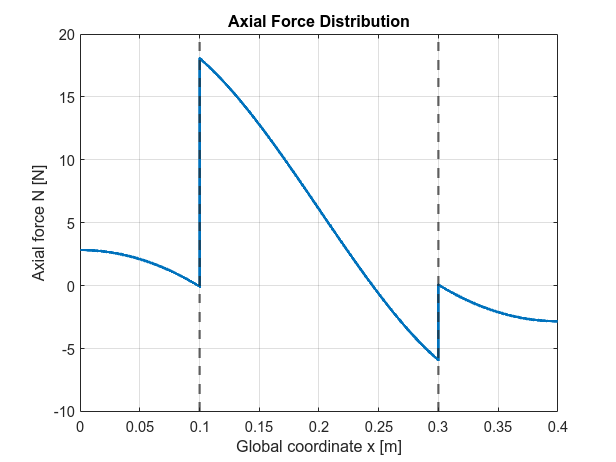


% ============================================================
% PLOT AXIAL FORCE
% ============================================================

figure;

plot(x_all,N_all,'LineWidth',2);

xline(L1,'--','LineWidth',1.5);
xline(L1+L2,'--','LineWidth',1.5);

grid on;

xlabel('Global coordinate x [m]');
ylabel('Axial force N [N]');
title('Axial Force Distribution');

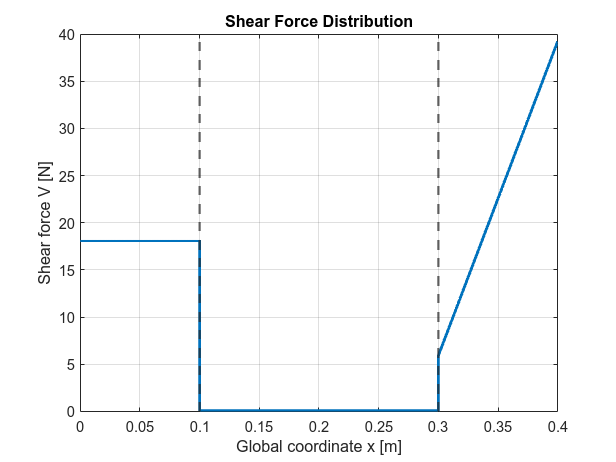



% ============================================================
% PLOT SHEAR FORCE
% ============================================================

figure;

plot(x_all,V_all,'LineWidth',2);

xline(L1,'--','LineWidth',1.5);
xline(L1+L2,'--','LineWidth',1.5);

grid on;

xlabel('Global coordinate x [m]');
ylabel('Shear force V [N]');
title('Shear Force Distribution');

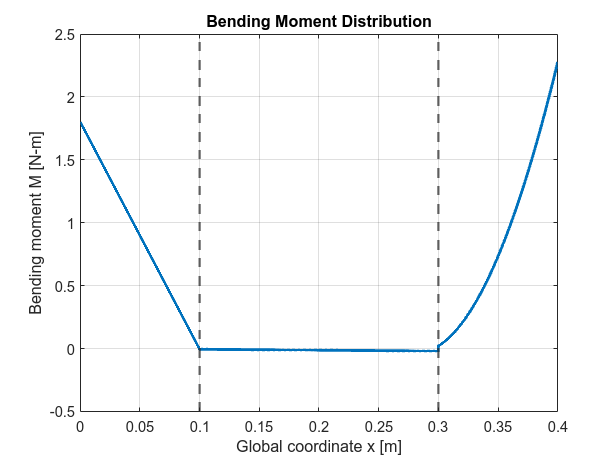


% ============================================================
% PLOT BENDING MOMENT
% ============================================================

figure;

plot(x_all,M_all,'LineWidth',2);

xline(L1,'--','LineWidth',1.5);
xline(L1+L2,'--','LineWidth',1.5);

grid on;

xlabel('Global coordinate x [m]');
ylabel('Bending moment M [N-m]');
title('Bending Moment Distribution');


% STRESS CALCULATION

% Effective area used for axial stress
A_eff = As;

% Distance from neutral axis to extreme fibre
y_max = length_flange;

% Material yield strength
sigma_yield = 276e6;       % [Pa]

% NORMAL STRESS FROM AXIAL FORCE

sigma_N1 = N1_num/A_eff;
sigma_N2 = N2_num/A_eff;
sigma_N3 = N3_num/A_eff;

% BENDING STRESS
I_y_c_section = t_boom*length_flange^3/6

I_y_c_section = 2.6042e-09


sigma_B1 = -M1_num*y_max/I_y_c_section;
sigma_B2 = -M2_num*y_max/I_y_c_section;
sigma_B3 = -M3_num*y_max/I_y_c_section;

% TOTAL NORMAL STRESS

sigma_1 = sigma_N1 + sigma_B1;
sigma_2 = sigma_N2 + sigma_B2;
sigma_3 = sigma_N3 + sigma_B3;

% SHEAR STRESS

% Approximate effective shear area
A_shear = As;

tau_1 = V1_num/A_shear;
tau_2 = V2_num/A_shear;
tau_3 = V3_num/A_shear;

% VON MISES STRESS

sigma_vm1 = sqrt(sigma_1.^2 + 3*tau_1.^2);
sigma_vm2 = sqrt(sigma_2.^2 + 3*tau_2.^2);
sigma_vm3 = sqrt(sigma_3.^2 + 3*tau_3.^2);

% COMBINE ALL SECTIONS

sigma_N_all = [sigma_N1 sigma_N2 sigma_N3];

sigma_B_all = [sigma_B1 sigma_B2 sigma_B3];

sigma_all = [sigma_1 sigma_2 sigma_3];

tau_all = [tau_1 tau_2 tau_3];

sigma_vm_all = [sigma_vm1 sigma_vm2 sigma_vm3];

% MAXIMUM STRESSES


sigma_N_max = max(abs(sigma_N_all));

sigma_B_max = max(abs(sigma_B_all));

sigma_max = max(abs(sigma_all));

tau_max = max(abs(tau_all));

sigma_vm_max = max(sigma_vm_all);


fprintf('STRESS RESULTS\n');

STRESS RESULTS




fprintf('Maximum axial stress       = %.6f MPa\n',sigma_N_max/1e6);

Maximum axial stress       = 0.278034 MPa



fprintf('Maximum bending stress     = %.6f MPa\n',sigma_B_max/1e6);

Maximum bending stress     = 21.863539 MPa



fprintf('Maximum normal stress      = %.6f MPa\n',sigma_max/1e6);

Maximum normal stress      = 21.907083 MPa



fprintf('Maximum shear stress       = %.6f MPa\n',tau_max/1e6);

Maximum shear stress       = 0.603567 MPa



fprintf('Maximum von Mises stress   = %.6f MPa\n',sigma_vm_max/1e6);

Maximum von Mises stress   = 21.932012 MPa



FoS = sigma_yield/sigma_vm_max;

fprintf('Yield strength             = %.6f MPa\n',sigma_yield/1e6);

Yield strength             = 276.000000 MPa


fprintf('Factor of Safety            = %.4f\n',FoS);

Factor of Safety            = 12.5843
